## **Introduction to space Geodesy (WinSem 24/25):**

## **Assignment 4: Reference systems and transformations**

- **Awsam Agbaria (0501833) - awsam.agbaria@campus.tu-berlin.de**

- **Tarik Abu Mukh (0501953) - t.abu.mukh@campus.tu-berlin.de**

- **Francesco Cherubini (0515856) - francesco.cherubini@campus.tu-berlin.de**

- **Zilong Liu (0501297) -  zilong.liu@campus.tu-berlin.de**

- **Mathimenaka Ramasamy (0501301) - mathimenaka.ramasamy@campus.tu-berlin.de**

### Question 1 testing: Precession of a fictitious celestial object

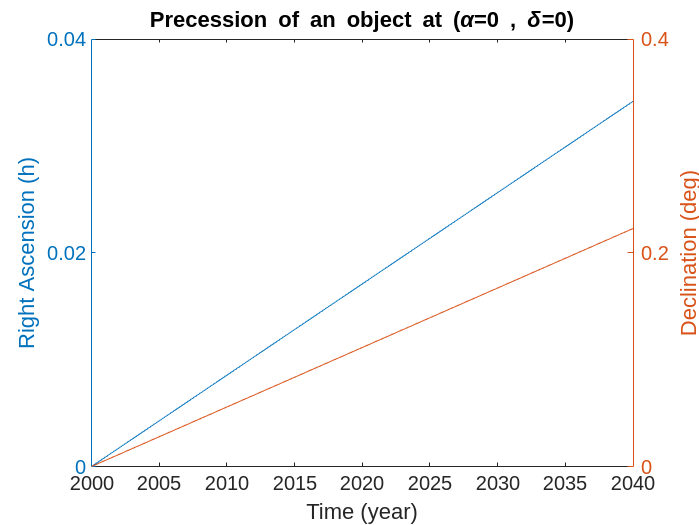

deltas = [];
alphas = [];
% coordinates of a fictitious celestial object at the vernal equinox
alpha = 0;
delta = 0;
% Converted to Cartesian
xi0 = [];
[xi0(1),xi0(2),xi0(3)] = spherical_to_cartesian(delta, alpha, 1);
xi0 = xi0.';
% Resolution
yyyy=2000:2040;
mm=1;dd=1; ut1=12; minute=0; second=0;
for y=yyyy
    % Calculate Julian Day
    curr_jd = gre2jd(y,mm,dd,ut1,minute,second);
    % Calculate The nutation matrix
    prec_mat = precession(curr_jd);
    % Multiply with vector
    xip = prec_mat * xi0;
    % Convert back to Celestial coordinates in original units
    [delta_res, alpha_res, radi] = cartesian_to_spherical(xip(1), xip(2), xip(3));
    deltas(end+1) = delta_res;
    alphas(end+1) = alpha_res/15;
end
[hAx,hLine1,hLine2] = plotyy(yyyy, alphas, yyyy, deltas);
title("Precession of an object at (\alpha=0 , \delta=0)");
ylabel(hAx(1),"Right Ascension (h)") % left y-axis 
ylabel(hAx(2),"Declination (deg)") % right y-axis
xlabel(hAx, "Time (year)")

### Question 2 testing: Nutation of a fictitious celestial object

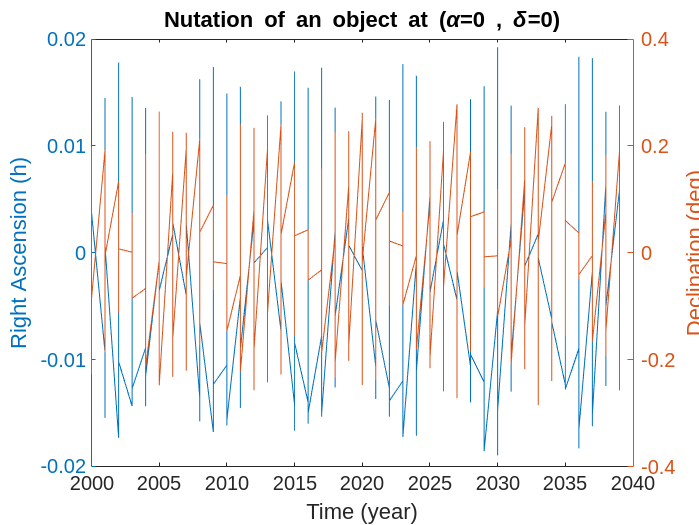

deltas = [];
alphas = [];
% coordinates of a fictitious celestial object at the vernal equinox
alpha = 0;
delta = 0;
% Converted to Cartesian
xi0 = [];
[xi0(1),xi0(2),xi0(3)] = spherical_to_cartesian(delta, alpha, 1);
xi0 = xi0.';
% Resolution
yyyy=2000:2039;
mm=1:12;
dd=1; ut1=12; minute=0; second=0;
for y=yyyy
    for m=mm
        % Calculate Julian Day
        curr_jd = gre2jd(y,m,dd,ut1,minute,second);
        % Calculate The nutation matrix
        nut_mat = nutation(curr_jd);
        % Multiply with vector
        xip = nut_mat * xi0;
        % Convert back to Celestial coordinates in original units
        [delta_res, alpha_res, radi] = cartesian_to_spherical(xip(1), xip(2), xip(3));
        deltas(end+1) = delta_res;
        alphas(end+1) = alpha_res/15;
    end
end
x = repelem(yyyy,12);
[hAx,hLine1,hLine2] = plotyy(x, alphas, x, deltas);
title("Nutation of an object at (\alpha=0 , \delta=0)");
ylabel(hAx(1),"Right Ascension (h)") % left y-axis 
ylabel(hAx(2),"Declination (deg)") % right y-axis
xlabel(hAx, "Time (year)")

### Question 3 testing: Polar motion

format long
polar_motion_matrix(2024,2,29,1,23)

ans =    0.999999999999999  -0.000000000000048  -0.000000037221611
                   0   0.999999999999156  -0.000001299073214
   0.000000037221611   0.000001299073214   0.999999999999156


### Question 4 testing: Coordinate calculation

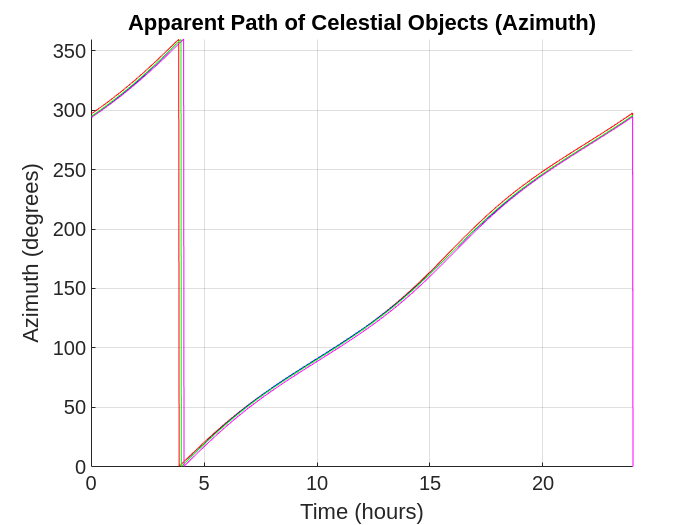

Lambda = 13 + 26/60; % Observatory longitude in degrees
Phi = 52 + 34/60;    % Observatory latitude in degrees
Lambda_rad = deg2rad(Lambda);
Phi_rad = deg2rad(Phi);

% Time settings
yyyy = 2024;
mm = 01;
dd = 11;
date_modifiedjd = gre2jd(yyyy,mm,dd,0,0,0) - 2400000.5; % Modified Julian date

% Load ICRF3 coordinates (alpha, delta)
icrf3 = [
    % alpha (h, m, s), delta (deg, min, sec)
    5*15 + 8/60 + 42.36351222/3600, 84 + 32/60 + 4.5441733/3600;
    11*15 + 3/60 + 52.22168463/3600, -(53 + 57/60 + 0.6966389/3600);
    11*15 + 13/60 + 58.69508613/3600, 14 + 42/60 + 26.9526507/3600;
    17*15 + 39/60 + 27.39049431/3600, 49 + 55/60 + 3.3683385/3600;
];

% Convert alpha to degrees and then to radians
alpha_rad = deg2rad(icrf3(:, 1)); % alpha in degrees
delta_rad = deg2rad(icrf3(:, 2));      % delta in radians

[xi0(1),xi0(2),xi0(3)] = spherical_to_cartesian(delta_rad(1),alpha_rad(1),1);

% Placeholder for results
azimuths = zeros(length(times), size(icrf3, 1)); % Azimuth for each object at each time
elevations = zeros(length(times), size(icrf3, 1)); % Elevation for each object at each time

% Time independent matrix
R3_Lambda = rot3d(Lambda_rad,3); % Rotation by -Lambda
R2_Phi = rot3d(pi/2 - Phi_rad,2); % Rotation by (90 - Phi)
M1 = mir3d(1); % Reflection matrix
TID_M = M1 * R2_Phi * R3_Lambda;

% Time dependent: Iterate over each time step
for t = 0:1439
    % Calculate GMST
    m = mod(t,60);
    h = floor(t/60);
    jd = gre2jd(yyyy,mm,dd,h,m,0);
    T = (jd - 2451545.0) / 36525;
    gmst = mod(280.46061837 + 360.98564736629 * (jd - 2451545) + 0.000387933*T^2 - T^3/38710000, 360);
    gmst_rad = deg2rad(gmst);
    
    % Polar motion (W matrix, from interpolation)
    W = polar_motion_matrix(yyyy,mm,dd,h,m); % Construct W matrix
    % Nutation matrix
    N = nutation(jd);
    % Precession matrix
    P = precession(jd);
    % Rotation matrix
    R = rot3d(gmst_rad,3);

    TD_M = TID_M * W * R * N * P;

    % Iterate over each ICRF3 object
    for obj = 1:size(icrf3, 1)
        % Compute initial vector in GCRS
        [xi0(1),xi0(2),xi0(3)] = spherical_to_cartesian(delta_rad(obj),alpha_rad(obj),1);
        % Transform to local horizon system
        x_g = TD_M * xi0;

        % Extract azimuth and elevation
        azimuths(t+1, obj) = atan2(x_g(2), x_g(1)); % Azimuth
        if azimuths(t+1, obj) < 0
         azimuths(t+1, obj) = azimuths(t+1, obj) + 2 * pi;
        end
        elevations(t+1, obj) = atan(x_g(3) / sqrt(x_g(1)^2 + x_g(2)^2)); % Elevation
    end
end

% Convert results to degrees
azimuths_deg = rad2deg(azimuths);
elevations_deg = rad2deg(elevations);

t = linspace(0, 24, 1441)';
% Display results
figure;
hold on;
plot(t, azimuths_deg(:,1), 'r', 'DisplayName', 'Object 1');
plot(t, azimuths_deg(:,2), 'b', 'DisplayName', 'Object 2');
plot(t, azimuths_deg(:,3), 'g', 'DisplayName', 'Object 3');
plot(t, azimuths_deg(:,4), 'm', 'DisplayName', 'Object 4');
hold off;
xlabel('Time (hours)');
ylabel('Azimuth (degrees)');
xlim([0 24]);
ylim([0 360]);
title('Apparent Path of Celestial Objects (Azimuth)');
grid on;

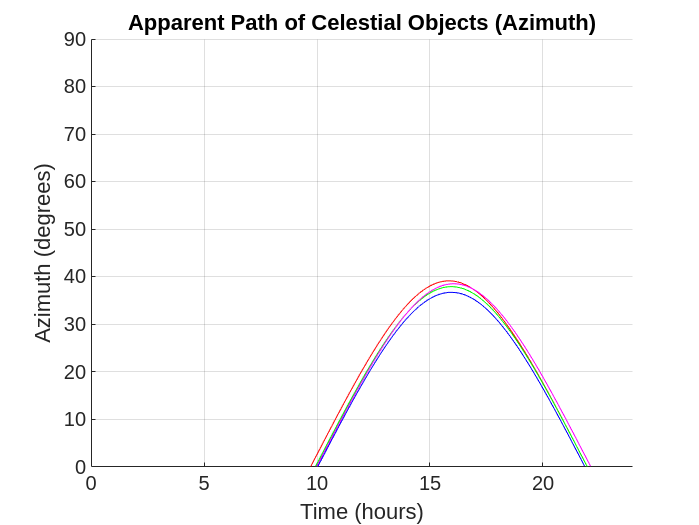

% Elevation
figure;
hold on;
plot(t, elevations_deg(:,1), 'r', 'DisplayName', 'Object 1');
plot(t, elevations_deg(:,2), 'b', 'DisplayName', 'Object 2');
plot(t, elevations_deg(:,3), 'g', 'DisplayName', 'Object 3');
plot(t, elevations_deg(:,4), 'm', 'DisplayName', 'Object 4');
hold off;
xlabel('Time (hours)');
ylabel('Azimuth (degrees)');
xlim([0 24]);
ylim([0 90]);
title('Apparent Path of Celestial Objects (Azimuth)');
grid on;

- Sky plotting the coordinates

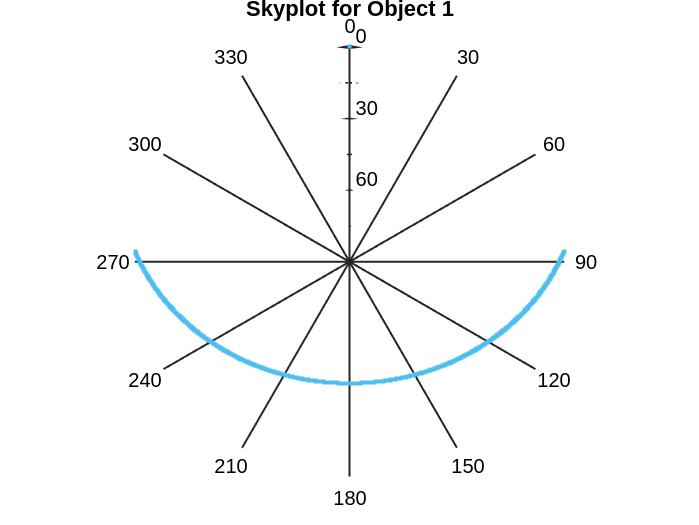

objects = {'Object 1', 'Object 2', 'Object 3', 'Object 4'}; % Object name

figure;
% Create Skyplot
% first object
zenith_angle = elevations_deg(:, 1);
zenith_angle(elevations(:, 1) < 0) = NaN;
p1 = skyplot(azimuths_deg(:, 1), zenith_angle,'.');
title(['Skyplot for ', objects{1}]);

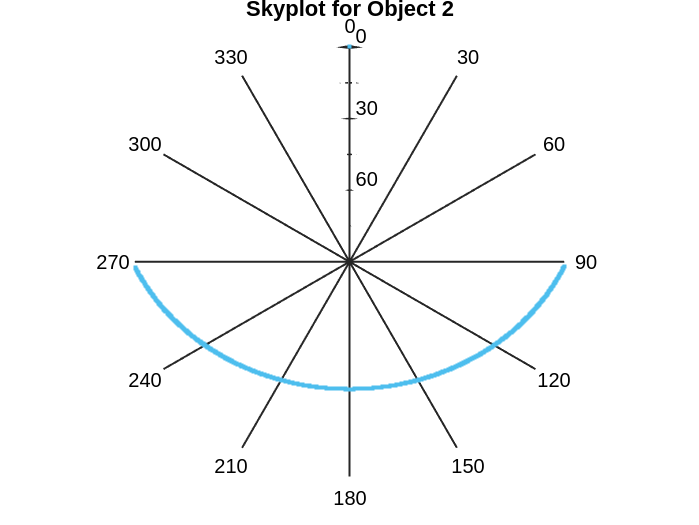

% second object
zenith_angle = elevations_deg(:, 2);
zenith_angle(elevations(:, 2) < 0) = NaN;
p2 = skyplot(azimuths_deg(:, 2), zenith_angle,'.');
title(['Skyplot for ', objects{2}]);

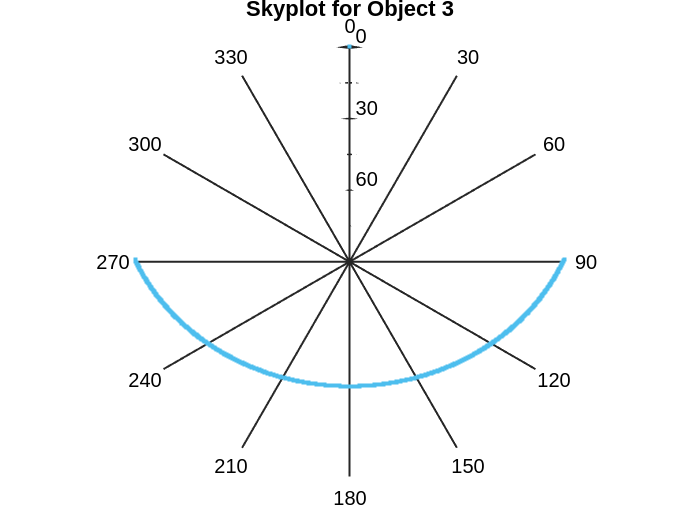

% third object
zenith_angle = elevations_deg(:, 3);
zenith_angle(elevations(:, 3) < 0) = NaN;
p3 = skyplot(azimuths_deg(:, 3), zenith_angle,'.');
title(['Skyplot for ', objects{3}]);

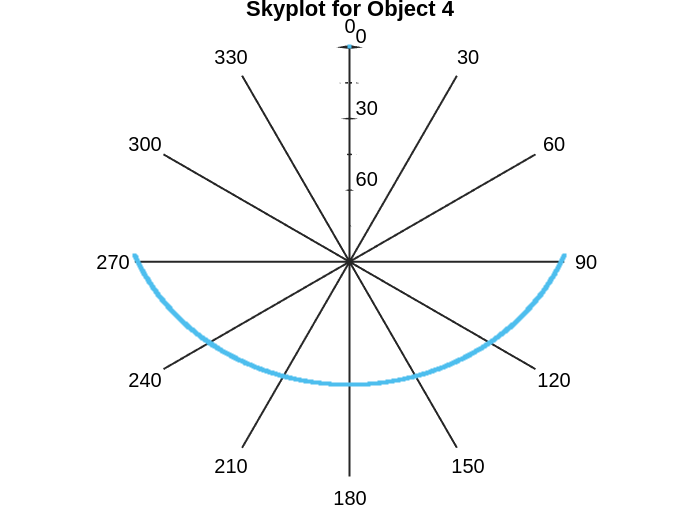

% fourth object
zenith_angle = elevations_deg(:, 4);
zenith_angle(elevations(:, 4) < 0) = NaN;
p4 = skyplot(azimuths_deg(:, 4), zenith_angle,'.');
title(['Skyplot for ', objects{4}]);